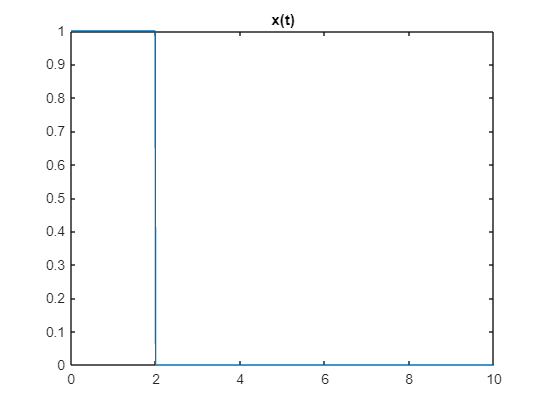

clc, close all, clear all

%Señal x(t)
a = 2;
b = 6;
u2 = @(t) (t>=0);
x =@(t) u2(t)-u2(t-a);

t1 = 0:0.01:10;

plot(t1,x(t1)), title('x(t)')


%Señal y(t)
h = @(t) u2(t)-u2(t-b);
y = conv(x(t1),h(t1),"full");
tconv = 0:0.01:20;
plot(tconv,y), title('conv')


Se concluye que el tiempo de la convolucion es la suma del tiempo inicial de ambas funciones hasta la suma del tiempo final de ambas funciones :)

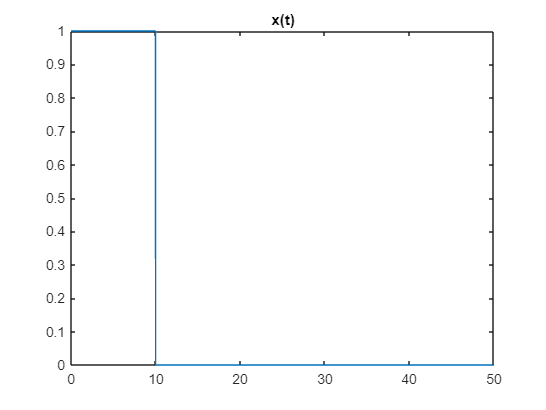

clc, close all, clear all

%señal x(t)
d1 = 10;
d2 = 40;
t = 0:0.01:50;

u = @(t) (t>=0);
x =@(t,d) u(t)-u(t-d);

plot(t,x(t,d1)), title('x(t)')

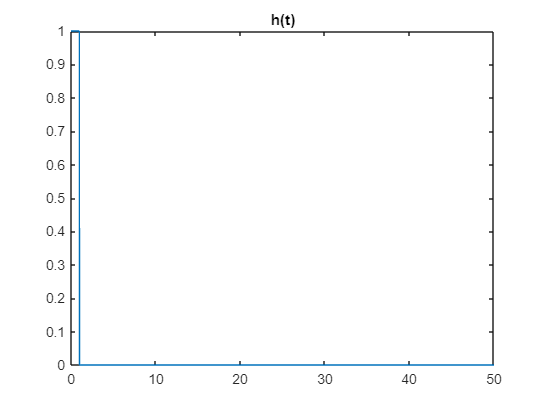


%Señal impulso unitario
delta = x(t,1);
plot(t,delta), title('h(t)')

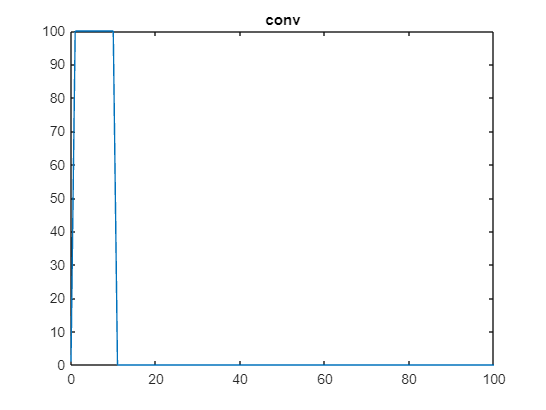


%Convolucion con d1
y1 = conv(x(t,d1),delta,"full");
time = 2*t(1):0.01:2*t(length(t));

plot(time,y1), title('conv')

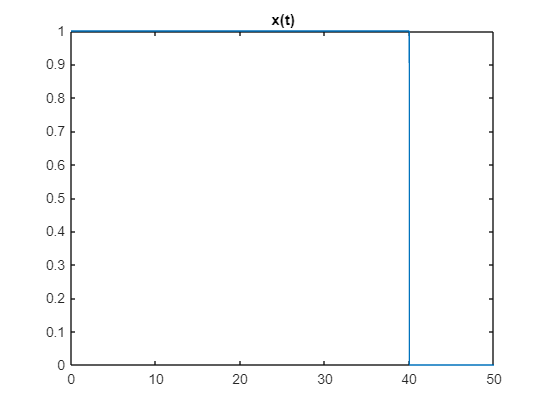


%Con d2
plot(t,x(t,d2)), title('x(t)')


%Convolucion con d2
y1 = conv(x(t,d2),delta,"full");
time = 2*t(1):0.01:2*t(length(t));

plot(time,y1), title('conv')


La señal cambia de forma haciendose más ancha